%clearing
clear;
clc;
close all;

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

   120    10



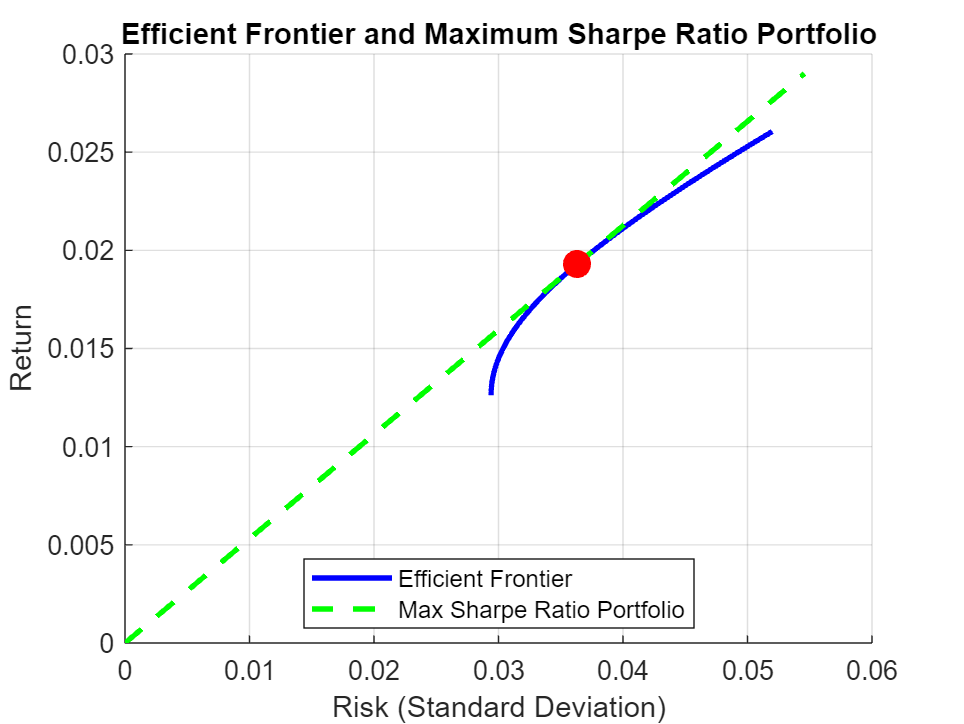

weights for the high sharpe ratio portfolio
    0.2901    0.0062    0.1878    0.1161    0.2495    0.2855   -0.1247    0.1200    0.0702   -0.2008

Maximum Sharpe Ratio: 0.53141
Expected Portfolio Return: 0.019334
Portfolio Risk (Standard Deviation): 0.036383


Output argument "max_sharpe_returns" (and possibly others) not assigned a value in the execution with "mvoframework" function.


[n, m] = size(cdata);
returns = zeros(n-1, m);
for j = 1:m
    for i = 2:n
        returns(i-1, j) = (cdata(i, j) - cdata(i-1, j)) / cdata(i-1, j);
    end
end

mean_returns = mean(returns)';
cov_matrix = cov(returns);
num_assets = size(mean_returns, 1);

%function [max_sharpe_weights, max_sharpe_returns, max_sharpe_risk]
% = mvoframework(mean_returns, cov_matrix, shortselltoggle)

msw = zeros(num_assets);
msret = zeros(num_assets);
msrisk = zeros(num_assets);
rf = 3.14/12;

[msw, msret, msrisk] = mvoframework(mean_returns, cov_matrix, 1, rf);